clc; clear; close all; 

## Load Data

Traindata = readtable('DailyDelhiClimateTrain.csv');
Testdata = readtable('DailyDelhiClimateTest.csv');

tempData_Train = Traindata.meantemp;
tempData_Test = Testdata.meantemp;

% Data preprocessing for training data
XTrain = tempData_Train(1:end-1);
YTrain = tempData_Train(2:end);
[XTrain_norm, XTrain_mu, XTrain_sigma] = zscore(XTrain);
[YTrain_norm, YTrain_mu, YTrain_sigma] = zscore(YTrain);

% Data preprocessing for test data 
XTest = tempData_Test(1:end-1);
YTest = tempData_Test(2:end);
[XTest_norm, XTest_mu, XTest_sigma] = zscore(XTest);
[YTest_norm, YTest_mu, YTest_sigma] = zscore(YTest);

sequenceLength = 300;


## Transformer

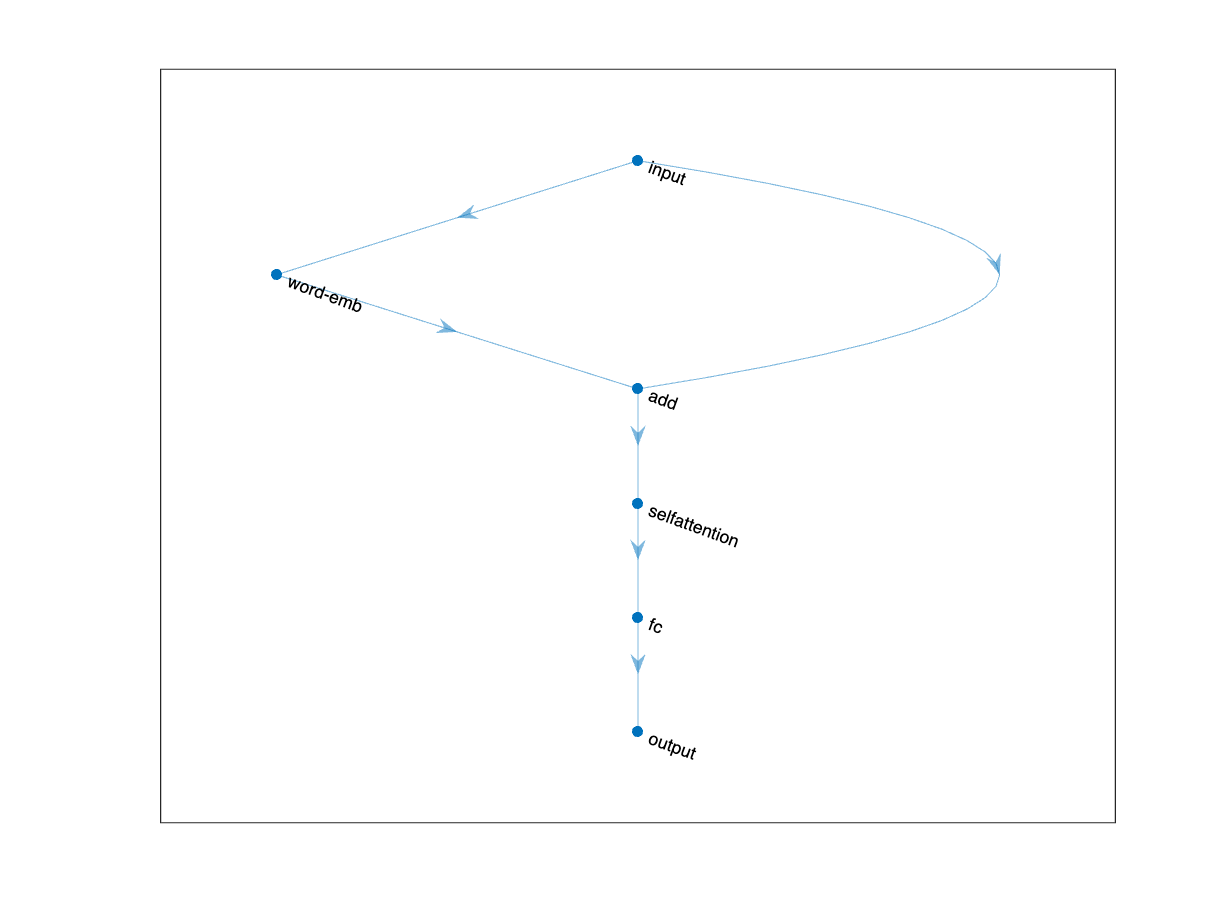

% Parameters
numChannels = 1;
embeddingOutputSize = 1;
maxPosition = sequenceLength+20;

% numHeads = 8;
numHeads = 8;

% numKeyChannels = 8*embeddingOutputSize;
numKeyChannels = numHeads*embeddingOutputSize;

layers = [ 
    sequenceInputLayer(numChannels,Name="input")
    positionEmbeddingLayer(embeddingOutputSize,maxPosition,PositionDimension="temporal", Name="word-emb");
    additionLayer(2,Name="add")
    selfAttentionLayer(numHeads,numKeyChannels)
    fullyConnectedLayer(1)
    regressionLayer('Name', 'output')];

lgraph = layerGraph(layers);

lgraph = connectLayers(lgraph,"input","add/in2");

plot(lgraph)

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         0.98 |          0.5 |          0.0010 |
|      10 |          50 |       00:00:03 |         0.79 |          0.3 |          0.0010 |
|      20 |         100 |       00:00:04 |         0.73 |          0.3 |          0.0010 |
|      30 |         150 |       00:00:05 |         0.66 |          0.2 |          0.0010 |
|      40 |         200 |       00:00:06 |         0.58 |          0.2 |          0.0010 |
|      50 |         250 |       00:00:07 |         0.50 |          0.1 |          0.0010 |
|      60 |         300 |       00:00:08 |         0.44 |      9.7

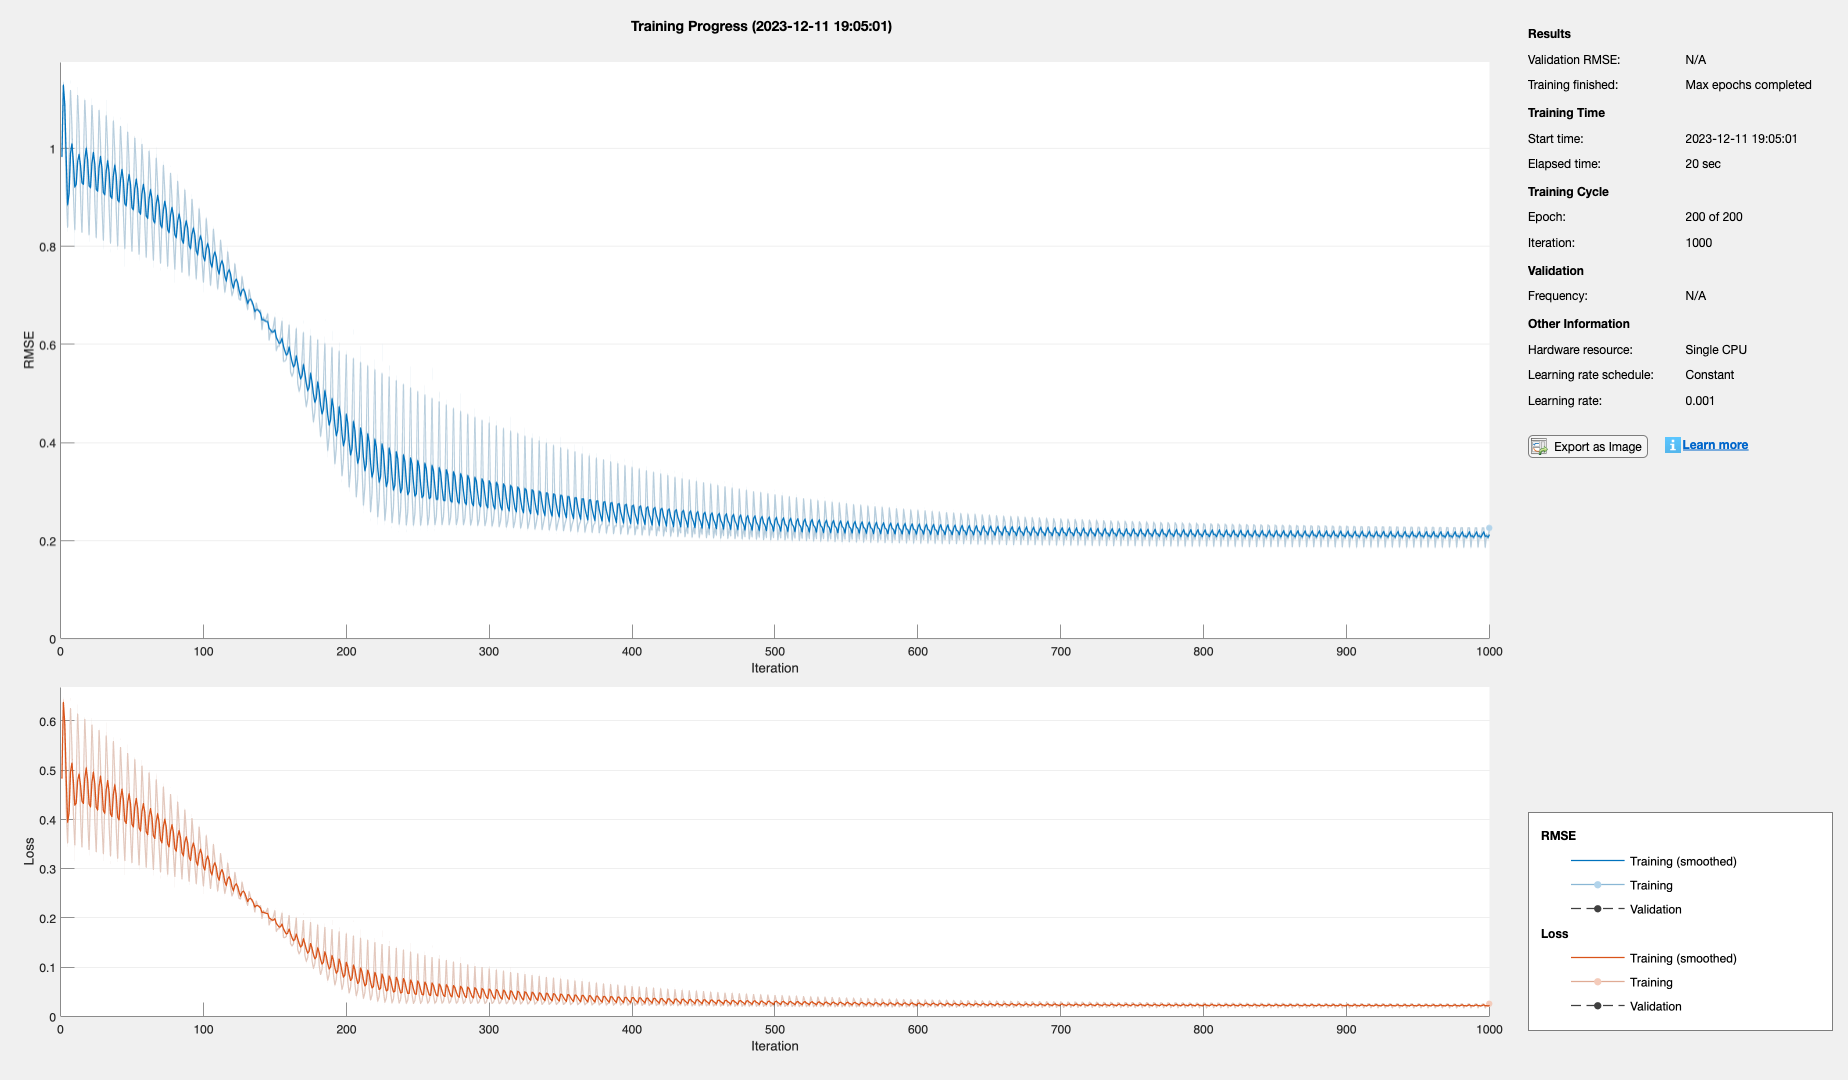

% Specify the options for training
% options = trainingOptions('adam', ...
%     'MaxEpochs', 200, ...
%     % 'MiniBatchSize', 32, ...
%     'MiniBatchSize', 64, ...
%     'SequenceLength', sequenceLength, 'Plots', ...
%     % 'training-progress');
%     'training-progress', 'LearnRateDropFactor', 0.9);

options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...
    'MiniBatchSize', 32, ...
    'SequenceLength', sequenceLength, 'Plots', ...
    'training-progress', 'LearnRateDropFactor', 0.9);

    % 'LearnRateSchedule', 'piecewise', ...
    % 'LearnRateDropFactor', 0.9, ...
    % 'LearnRateDropPeriod', 5, ...
    % 'InitialLearnRate', 0.001 ...
    %);

% Train the Transformer model
tic
net = trainNetwork(XTrain_norm', YTrain_norm', lgraph, options);

toc

Elapsed time is 25.030610 seconds.


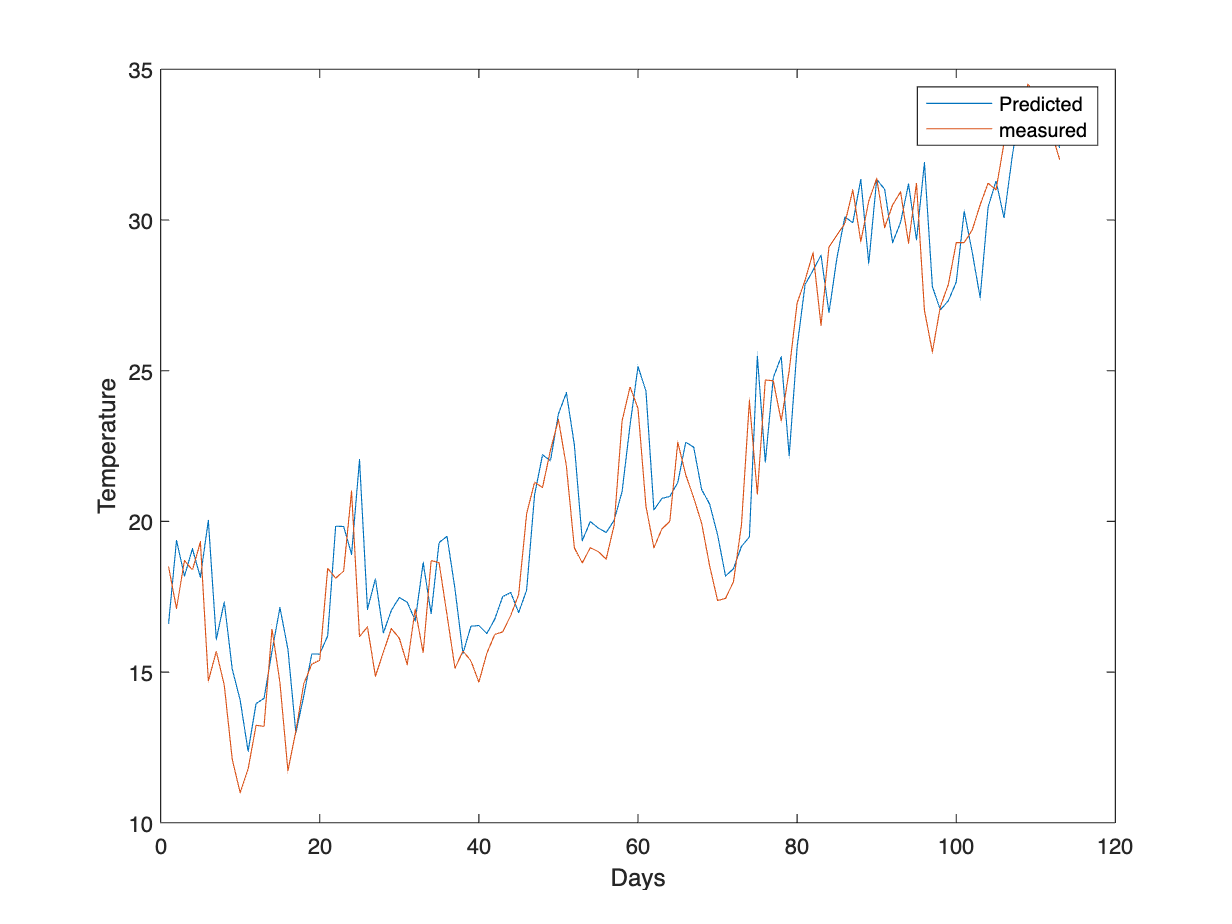

% Make predictions on a test sequence
yPrednorm = predict(net, XTest_norm');
yPred = yPrednorm*XTest_sigma+YTest_mu;

figure;
title("Test patition one-ahead predictions");
plot(yPred);
hold on 
plot(YTest);
hold off
legend('Predicted','measured')
xlabel('Days')
ylabel('Temperature');

% Performance
rmse_Transformer_Test_2 = rmse(yPred',YTest)

rmse_Transformer_Test_2 = single
1.9222